# Projeto do dia 30/10/2020

João Guilherme Martins Jatobá

18.01790-8

ECM303 - Sistemas de Controle

**Boas práticas**

clear all;
clc;
close all;

**Enunciado**


$$G_p(s)=\frac{1}{(s+1)(s+2)}$$


Forma canônica:


$$G_{mf}(s) = \frac{\omega_n^2}{s^2+2\zeta \omega s+\omega_n^2}$$


Desempenho

- Erro estacionário ao degrau nulo

- Pólos em malha fechada tenham amortecimento $\zeta=0.5$ e a frequência natural $w_n = 2 rad/s$


$$Polos = -\zeta w_n \pm jw_n\sqrt{1-\zeta^2}$$


syms s T

Mp = 0.1630

zeta = 0.5;


$$Mp=e^{\frac{-\pi\zeta}{\sqrt{1-\zeta^2}}}$$


Mp = exp((-pi*zeta)/(sqrt(1-zeta^2)))

Ts = 4

wn = 2;

$$Gp = \frac{1}{\left(s+1\right)\,\left(s+2\right)}$$

Ts = 4/(zeta*wn)
Gp = 1/((s+1)*(s+2))

**Transformação do processo para o domínio digital - incluir ZOH**


$$T(2\%)=\frac{4}{\zeta \omega} = 4s$$


N = 1

N = 1

D =conv([1 1],[1 2])

D =      1     3     2


Gp = tf(N,D)

Gp =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.




T=0.4

T = 0.4000

Gpz = c2d(Gp,T,'zoh') % Processo em digital

Gpz =
 
   0.05434 z + 0.03643
  ---------------------
  z^2 - 1.12 z + 0.3012
 
Sample time: 0.4 seconds
Discrete-time transfer function.



**Expressar o desempenho no domínio discreto - estimar T (amostragem)**

**//TODO**

wd = wn*sqrt(1-zeta^2);
fd = wd/(2*pi);

$$Gcz = \frac{\frac{16489\,z}{10000}-\frac{116560741}{100000000}}{z-1}$$

Td = 1/fd;

z =
 
  z
 
Sample time: 0.4 seconds
Discrete-time transfer function.



**Projetar o controlador Gc(z) no domínio discreto - sisotool**

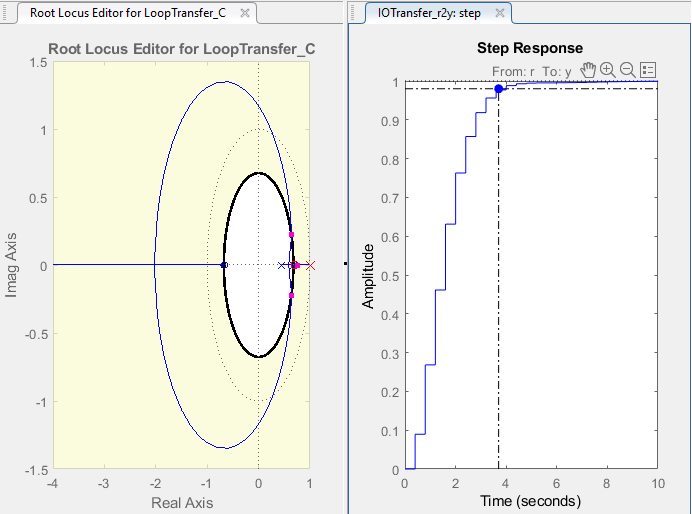

Pelo sisotool, achei este possível valor do controlador, com settling time $Ts = 3.7$ segundos e overshoot $Mp = 0\%$


$$C = \frac{1.6489(z-0.7069)}{z-1}$$


**Deteminar a equação de diferenças**

syms z
Gcz = 1.6489*(z-0.7069)/(z-1)
z = tf('z',T)

Gcz =
 
  1.649 z - 1.166
  ---------------
       z - 1
 
Sample time: 0.4 seconds
Discrete-time transfer function.



ExpFun = matlabFunction(Gcz);
ExpFun = str2func(regexprep(func2str(ExpFun), '\.([/^\\*])', '$1'));

Gza =
 
  0.08961 z^2 - 0.003278 z - 0.04246
  ----------------------------------
  z^3 - 2.12 z^2 + 1.421 z - 0.3012
 
Sample time: 0.4 seconds
Discrete-time transfer function.



Gcz = ExpFun(z)

Gzf =
 
  0.08961 z^2 - 0.003278 z - 0.04246
  ----------------------------------
  z^3 - 2.03 z^2 + 1.418 z - 0.3437
 
Sample time: 0.4 seconds
Discrete-time transfer function.




Gza = Gpz*Gcz
Gzf = feedback(Gza,1)




$$G_z = \frac{0.08961z^2-0.003278z-0.04246}{z^3-2.03z^2+1.418z-0.3437}$$



$$\frac{Y(z)}{U(z)} = G_z=\frac{0.08961z^{-1}-0.003278z^{-2}-0.04246z^{-3}}{1-2.03z^{-1}+1.418z^{-2}-0.3437z^{-3}}$$



$$Y*(1-2.03z^{-1}+1.418z^{-2}-0.3437z^{-3})=U*(0.08961z^{-1}-0.003278z^{-2}-0.04246z^{-3})$$



$$Y[K]=2.12Y[K-1]-1.421Y[K-2]+0.3012Y[K-3]+0.08961U[K-1]-0.003278U[K-2]-0.04246[U-3]$$


**Validar o controlador aplicando a euqção de diferenças (Matlab functon) ao processo Gp(s) - contínuo**